## Load Station Aloha Temperature data

T: temp (°C), t: time, z: depth (m)

clc;close;clear;clf
load HOTS_Temp.mat

Remove time average

Td = detrend(T',0)';

## EOFs and PCs can be computed directly from the data matrix using the Singular Value Decomposition 

## [U,S,V] = svd(Td);

## or from the eigenfunctions of the covariance matrix

## [e,lambda] = eig(Td'*Td);

## Show that the percent variance explained by the first 10 modes is equivalent using lambda or S^2.  Note, you may have to flip the order of lambda and e.

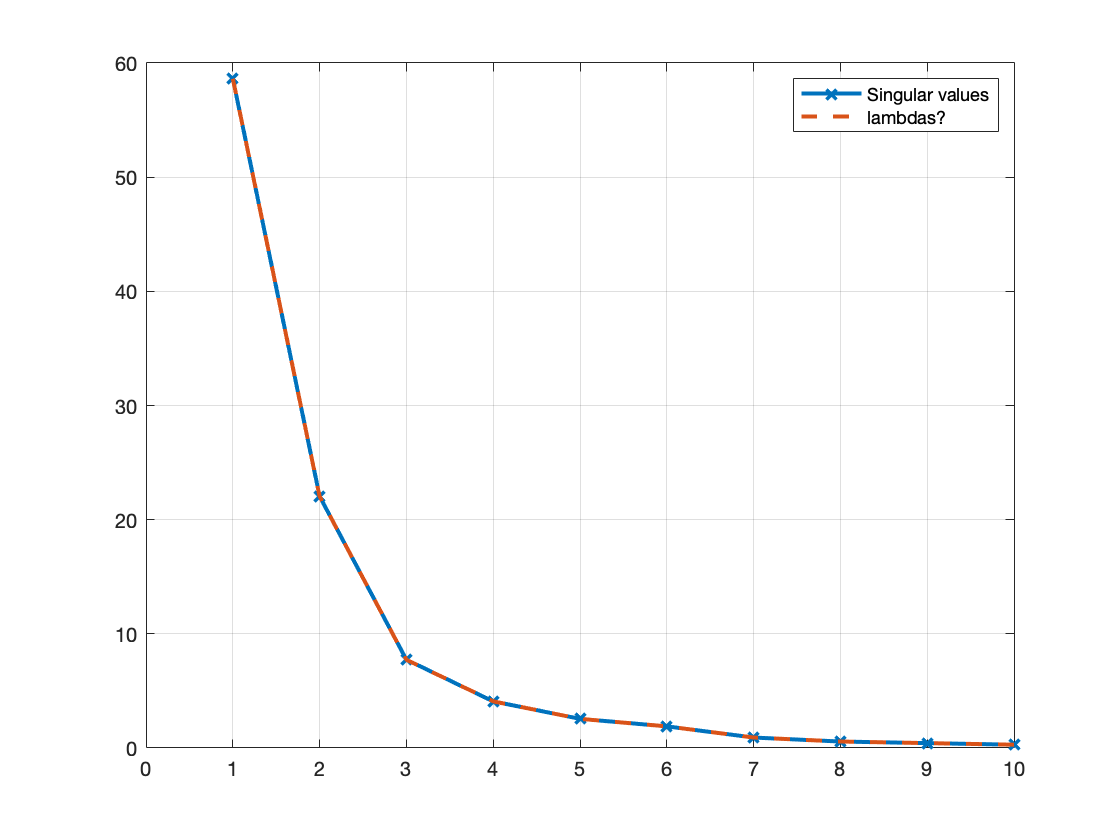

[U,S,V] = svd(Td);
sv = diag(S);
C = Td'*Td;
[e,lambda] = eig(C);
lambda = diag(lambda);
pvar = lambda/sum(lambda)*100;
e = fliplr(e); % flip stuff
lambda = flipud(lambda);
pvar = flipud(pvar); %% 
clf
plot(sv.^2/sum(sv.^2)*100,'-x','linewidth',2);hold on;plot(pvar,'--','linewidth',2)
xlim([0 10]);grid
legend({'Singular values','lambdas?'})

## Confirm that the EOFs from  V and E are equivalent,

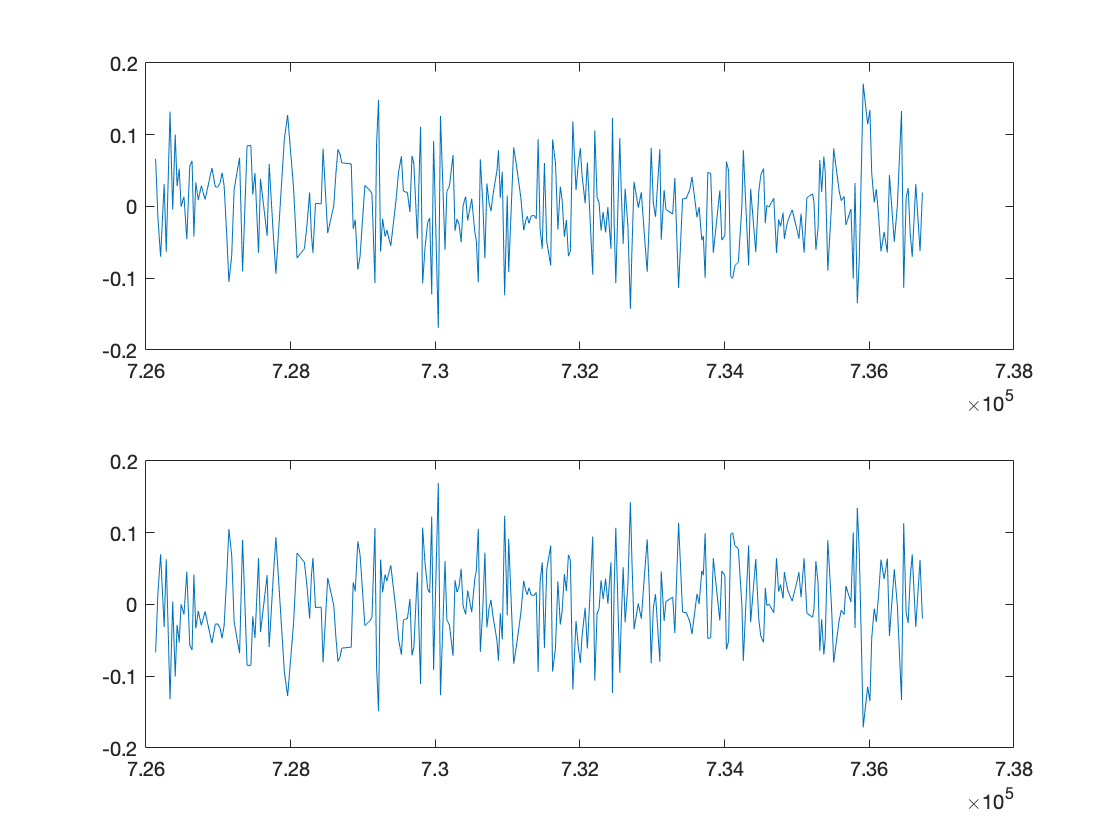


figure(2)
clf
subplot(2,1,1)
plot(t,e(:,1));
subplot(2,1,2)
plot(t,V(:,1))

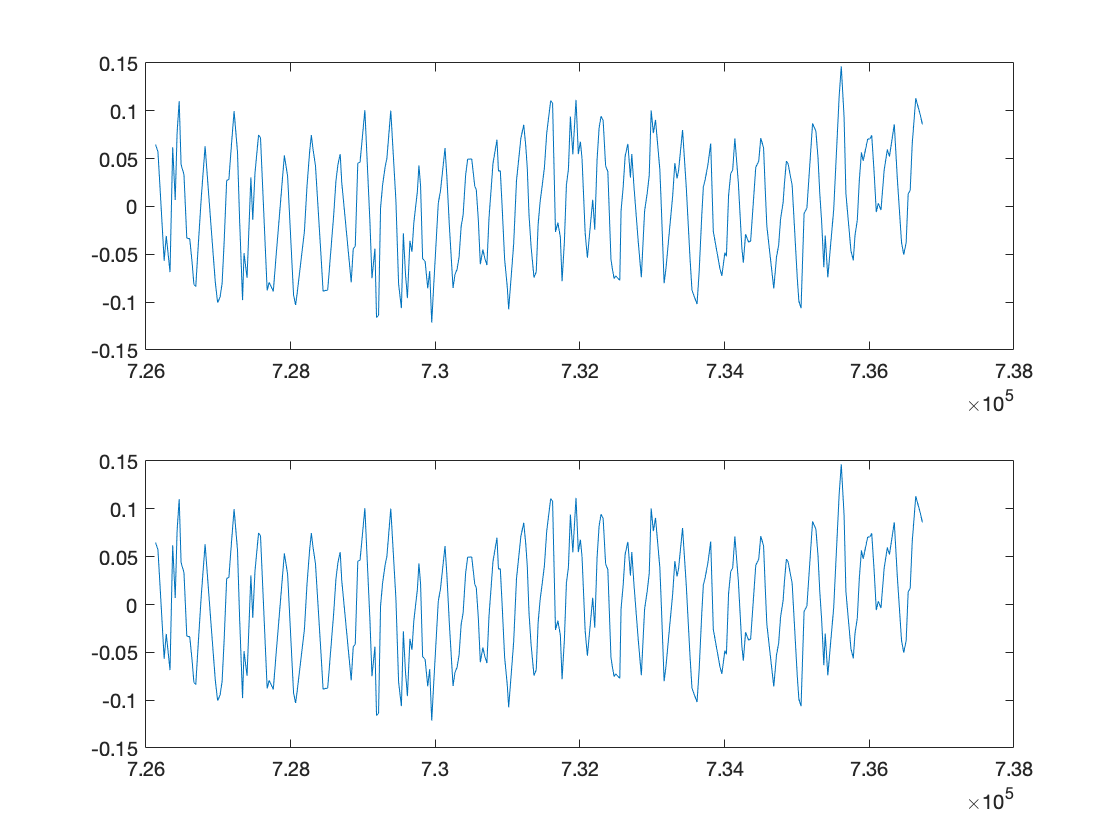

figure(3)
clf
subplot(2,1,1)
plot(t,e(:,2));
subplot(2,1,2)
plot(t,V(:,2))

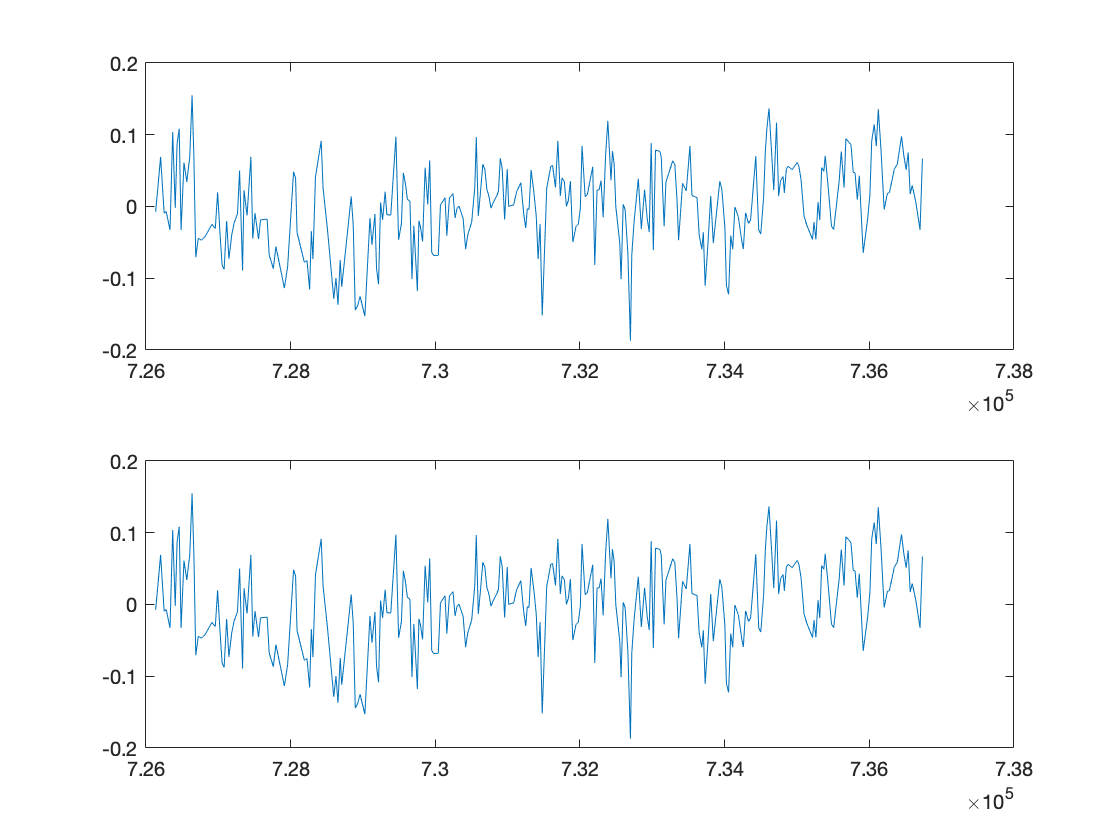



figure(4)
clf
subplot(2,1,1)
plot(t,e(:,3));
subplot(2,1,2)
plot(t,V(:,3))

**as well as the PCs from U*S and A = Td*e.**

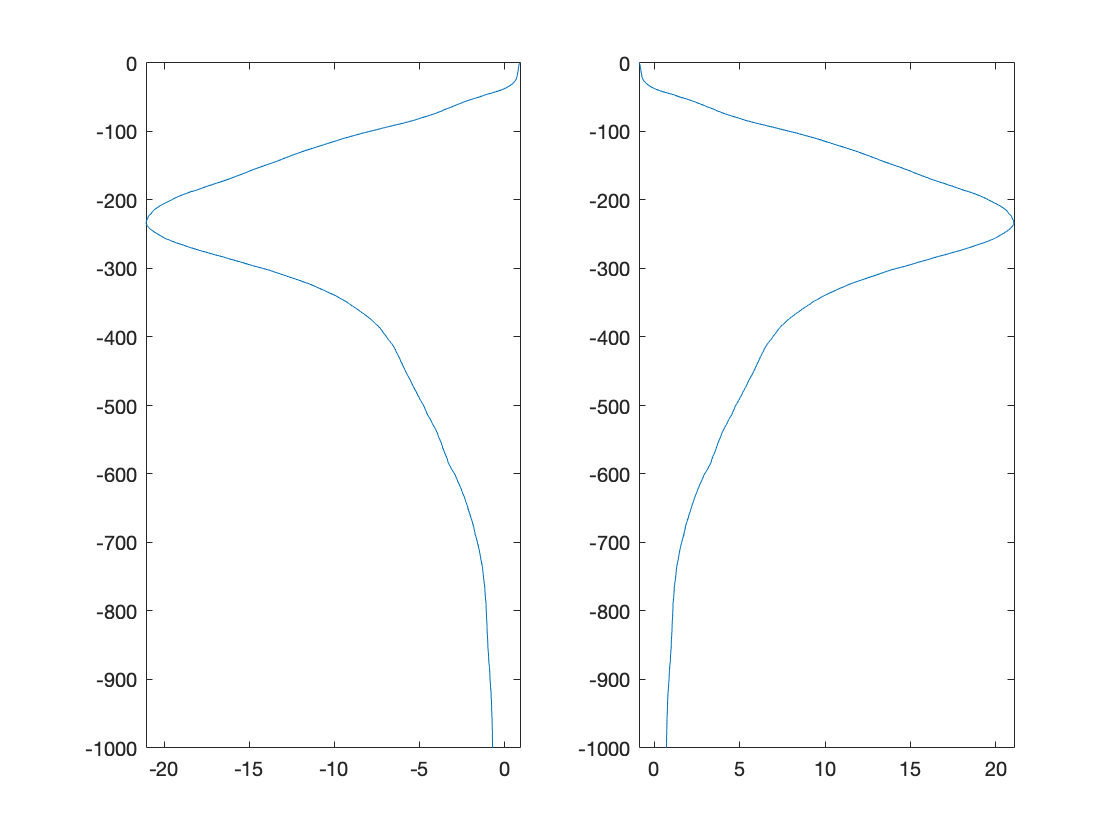

A = Td*e;
B=U*S;
figure(5)
clf
subplot(1,2,1)
plot(A(:,1),-z)
subplot(1,2,2)
plot(B(:,1),-z)

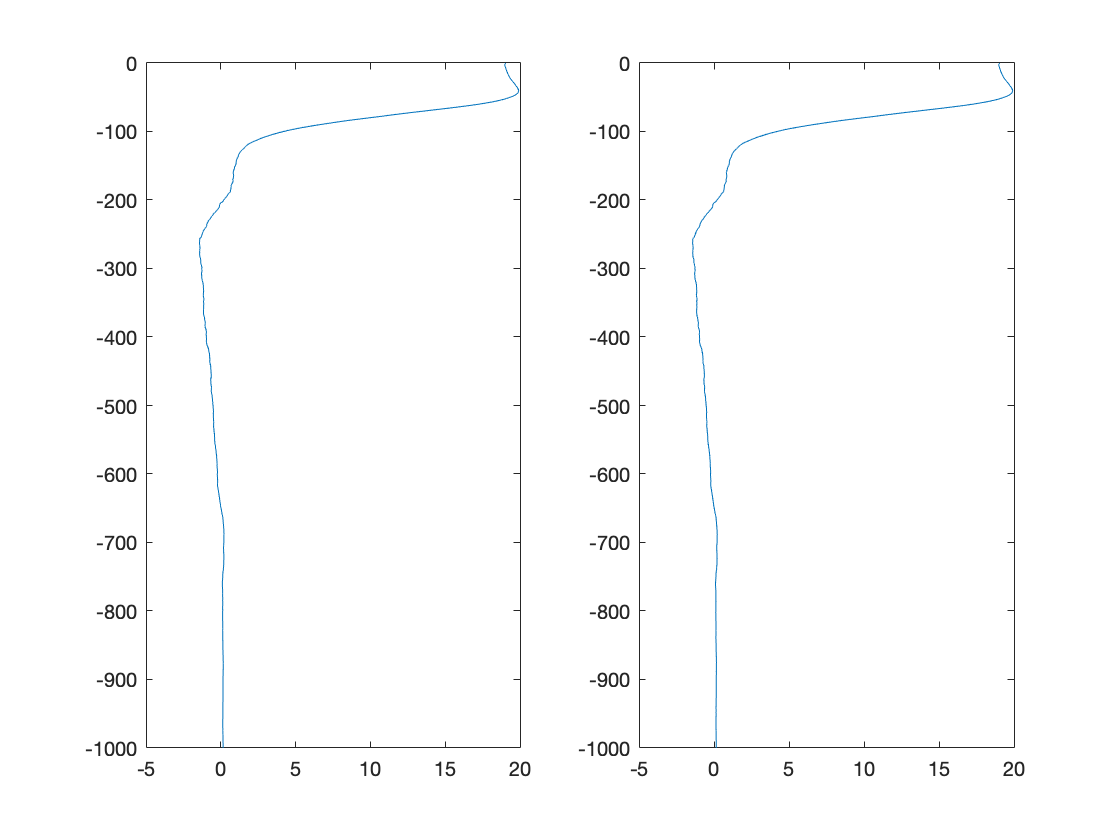

figure(6)
clf
subplot(1,2,1)
plot(A(:,2),-z)
subplot(1,2,2)
plot(B(:,2),-z)

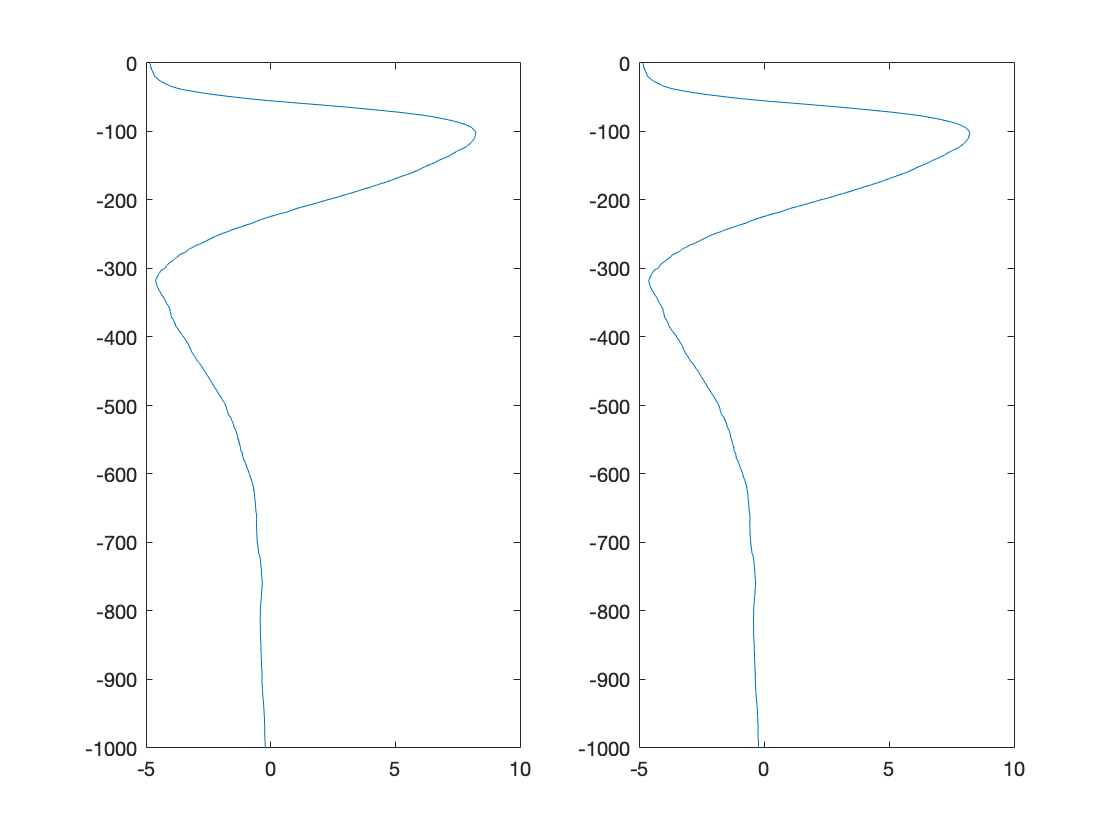

figure(7)
clf
subplot(1,2,1)
plot(A(:,3),-z)
subplot(1,2,2)
plot(B(:,3),-z)

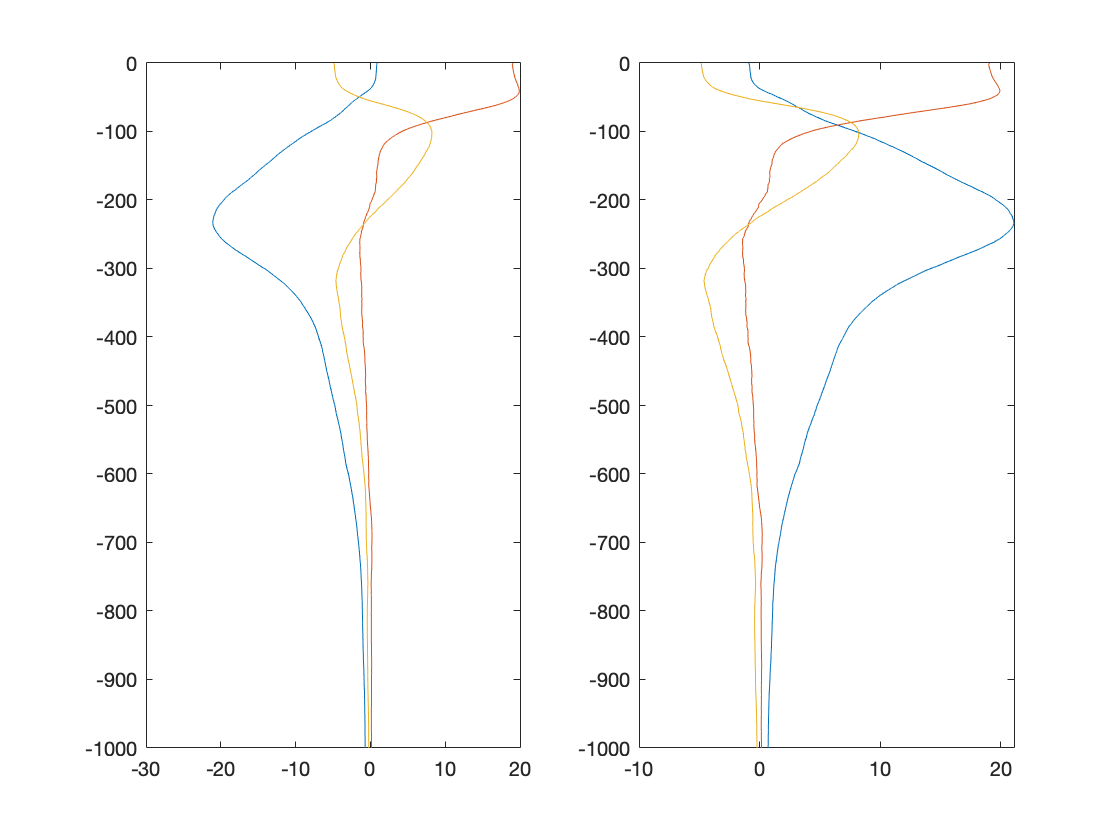

figure(8)
clf
subplot(1,2,1)
plot(A(:,1:3),-z)
subplot(1,2,2)
plot(B(:,1:3),-z)